## Load Data

[filename,path] = uigetfile('*.mat');
fulldata = load(fullfile(path,filename));
data = fulldata.data;
config = fulldata.config;
fileID = filename(1:5);

## Format Data

p0Idx = max(data(:,1))+1;
n0Idx = max(data(:,2))+1;
n0 = data(1:n0Idx,3);
p0 = data(1:n0Idx:end,4);
vb = reshape(data(:,5),n0Idx,[]).';
vt = reshape(data(:,6),n0Idx,[]).';

res = reshape(data(:,9),n0Idx,[]).';
thzX = reshape(data(:,7),n0Idx,[]).';
thzY = reshape(data(:,8),n0Idx,[]).';

thzYSm = smoothdata(smoothdata(thzY,1,'sgolay',5),2,'sgolay',5);
% thzYSm = thzYSm./(thzYSm(:,end));
% thzYSm = thzYSm./mean(thzYSm,1);

## Re-compute delta


$$\begin{array}{l}
n_0 =\left(1+\delta \;\right)v_{t\;} +\left(1-\delta \;\right)v_b \\
p_0 =\left(1+\delta \;\right)v_{t\;} -\left(1-\delta \;\right)v_b 
\end{array}$$


delta = 0.1925;
n0c = (1+delta).*vt + (1-delta).*vb;
p0c = (1+delta).*vt - (1-delta).*vb;

## Plot Resistance - n0,p0

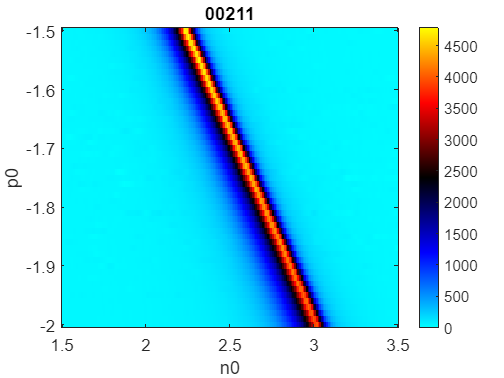

figure;
ax = axes;

imagesc(n0,p0,res);

ax.FontSize = 14;
ax.YDir = 'normal';
colormap(cm_bipolar);
colorbar();
xlabel('n0');
ylabel('p0');
title(fileID);

## Plot Resistance - vt,vb

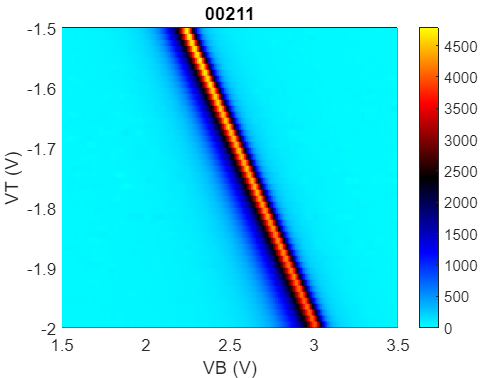

figure;
ax = axes;

pr = pcolor(vb,vt,res);
pr.LineStyle = 'none';

ax.FontSize = 14;
ax.YDir = 'normal';
colormap(cm_bipolar);
colorbar();
xlabel('VB (V)');
ylabel('VT (V)');
title(fileID);

## Plot THz - n0,p0

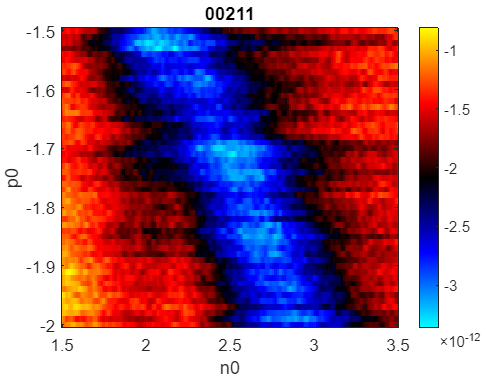

figure;
ax = axes;

imagesc(n0,p0,thzY);

ax.FontSize = 14;
ax.YDir = 'normal';
colormap(cm_bipolar);
colorbar();
xlabel('n0');
ylabel('p0');
title(fileID);

## Plot THz - vt,vb

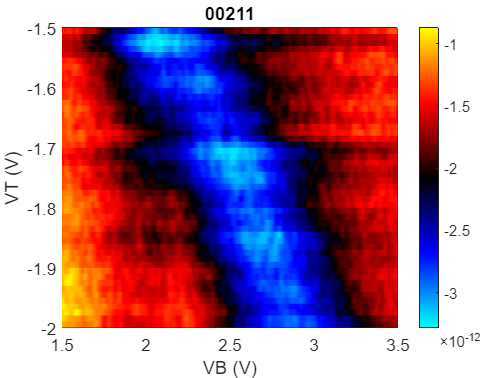

figure;
ax = axes;

pc = pcolor(vb,vt,thzYSm);
pc.LineStyle = 'none';

ax.FontSize = 14;
ax.YDir = 'normal';
colormap(cm_bipolar);
colorbar();
xlabel('VB (V)');
ylabel('VT (V)');
title(fileID);

## Plot Res/THz - n,D

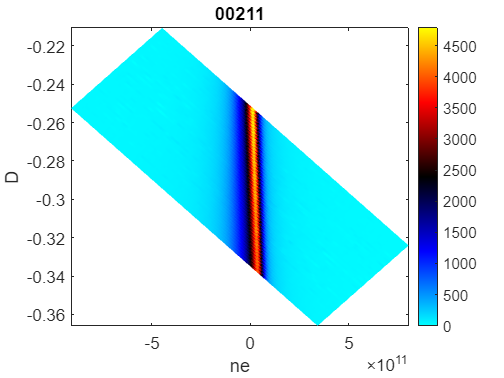

D = p0c.*0.07022;
ne = n0c.*0.77612e12;

figure;
ax = axes;

% pc = pcolor(ne,D,thzYSm./mean(thzYSm,2));
pc = pcolor(ne,D,res);
pc.LineStyle = 'none';

set(pc, 'AlphaData', 1-isnan(thzY));
ax.FontSize = 14;
ax.YDir = 'normal';
colormap(cm_bipolar);
colorbar();
xlabel('ne');
ylabel('D');
title(fileID);